# pix2pix - Image to Image Translation

## Installation

Run the function `install.m` to ensure that all required files are added to the MATLAB path.

install();

## Training the model

To train a model you need many pairs of images of "before" and "after". The classic example is the [facades dataset](http://cmp.felk.cvut.cz/~tylecr1/facade/) which contains label images of the fronts of buildings, and the corresponding original photo.

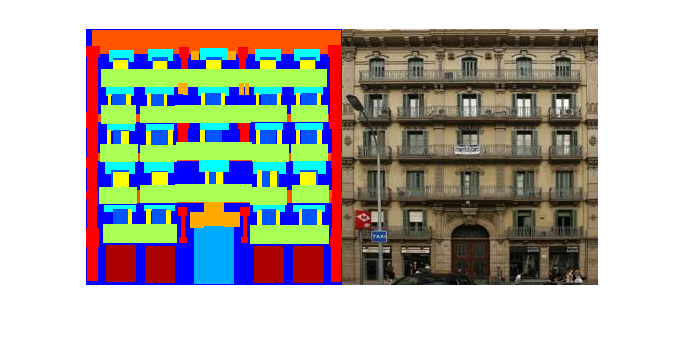

exampleInput = imread("docs/labels.png");
exampleTarget = imread("docs/target.jpg");
imshowpair(exampleInput, exampleTarget, "montage");

Use the helper function `p2p.util.downloadFacades` to download and prepare the dataset for model training. Once that's ready you will have two folders 'A' the input labels, and 'B' the desired output images. 

To train the model we need to provide the locations of the A and B images, as well as any training options, and the model will try and learn to convert A images into B images!

[labelFolder, targetFolder] = p2p.util.downloadFacades();

We will just use the default options which approximately reproduce the setttings from the original pix2pix paper.

options = p2p.trainingOptions();

Note training the model will take several hours on a GPU and requires around 6GB of GPU memory.

p2pModel = p2p.train(labelFolder, targetFolder, options);

## Generating images

Once the model is trained we can use the generator to make generate a new image. 

**Note:** The generator network expects the input image to have dimensions which are a multiple of 256 due to the down/up sampling methods. Our example image is already the right size, but if you wanted to resize an image to have appropriate dimensions be careful to use the correct resizing method for label images.

exampleInput = imresize(exampleInput, [256, 256], "Method", "nearest");

We can then use the `p2p.translate` function to convert the input image using trained model.

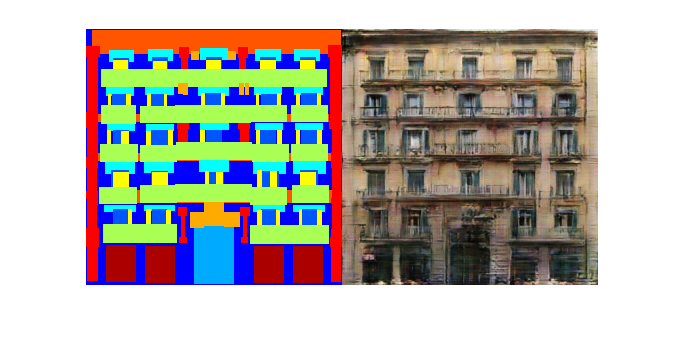

exampleOutput = p2p.translate(p2pModel, exampleInput);
imshowpair(exampleInput, exampleOutput, "montage");

*Copyright 2020 The MathWorks, Inc.*